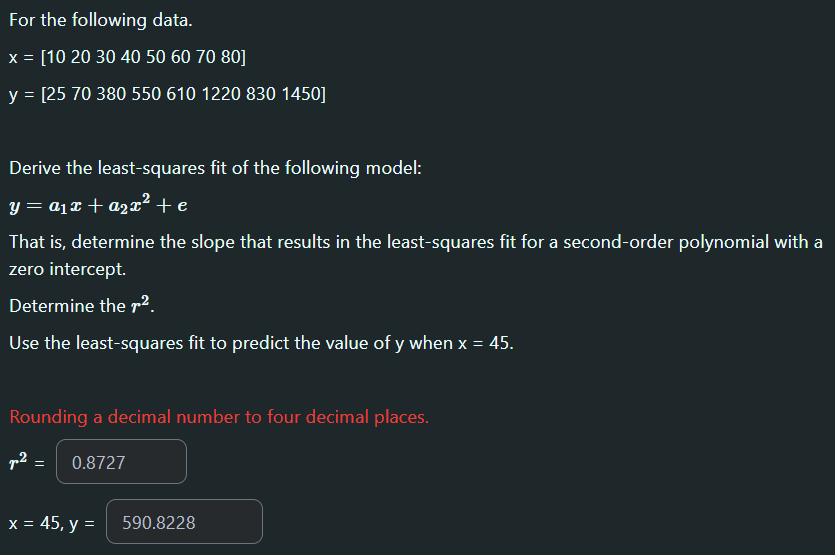

x = [10 20 30 40 50 60 70 80]';
y = [25 70 380 550 610 1220 830 1450]';

z = [x x.^2]

z =           10         100
          20         400
          30         900
          40        1600
          50        2500
          60        3600
          70        4900
          80        6400


% z = [ones(size(x)) x x.^2]
% z = [ones(size(x)) x]
% z = [ones(size(x)) x x.^2 x.^3]
% z = [ones(size(x)) x1 x2]
a = (z'*z) \ (z'*y)

a =     7.7710
    0.1191



Sr = sum((y-z*a).^2);
St = sum((y-mean(y)).^2);
r2 = round(1 - Sr/St,4)

r2 = 0.8727


xtest = 45;
pred_y = round(a(1).*xtest + a(2).*xtest.^2,4);
pred_y = round(pred_y,4)

pred_y = 590.8228